## Task 3

% 3.c.
P = 100000;                               % Stopping criterion
C = 10;                                   % Link capacity in Mbps
lambda = 1500;                            % Values for packet rate in pps
f = 10000;                                % Queue size(in bytes)

N = 20;                                   % number of simulation
n = [10, 20, 30, 40];                     % number of adidional VoIP packets flows

pkt_delay_voip = zeros(1, length(lambda));
error_delay_voip = zeros(1, length(lambda));
pkt_loss_voip = zeros(1, length(lambda)); 
error_loss_voip = zeros(1, length(lambda)); 

pkt_delay_data = zeros(1, length(lambda));
error_delay_data = zeros(1, length(lambda));
pkt_loss_data = zeros(1, length(lambda));  
error_loss_data = zeros(1, length(lambda));  

AVERAGE = zeros(4,4);
TERM = zeros(4,4);

for j = 1:length(n)
    PLd = zeros(1, N);
    PLv = zeros(1, N);
    APDd = zeros(1, N);
    APDv = zeros(1, N);
    MPDd = zeros(1, N);
    MPDv = zeros(1, N);
    TT = zeros(1, N);
    
    for i = 1:N
        [PLd(i), PLv(i), APDd(i), APDv(i), MPDd(i), MPDv(i), TT(i)] = Simulator4A(lambda,C,f,P,n(j));
    end    
    alfa = 0.1; % 90% confidence interval 
    
    
    AVERAGE = mean(PLd);
    TERM = norminv(1-alfa/2)*sqrt(var(PLd)/N);
    fprintf("Packet Loss (%%)  = %.2e +- %.2e\n", AVERAGE, TERM);
    pkt_loss_data(j) = AVERAGE;
    error_loss_data(j) = TERM;

    AVERAGE = mean(APDd);
    TERM = norminv(1-alfa/2)*sqrt(var(APDd)/N);
    fprintf("Av. Packet Delay Data (ms)  = %.2e +- %.2e\n\n\n", AVERAGE, TERM);
    pkt_delay_data(j) = AVERAGE;
    error_delay_data(j) = TERM;

    AVERAGE = mean(PLv);
    TERM = norminv(1-alfa/2)*sqrt(var(PLv)/N);
    fprintf("Packet Loss VoIP (%%)  = %.2e +- %.2e\n", AVERAGE, TERM);
    pkt_loss_voip(j) = AVERAGE;
    error_loss_voip(j) = TERM;

    AVERAGE = mean(APDv);
    TERM = norminv(1-alfa/2)*sqrt(var(APDv)/N);
    fprintf("Av. Packet Delay VoIP (ms)  = %.2e +- %.2e\n", AVERAGE, TERM);
    pkt_delay_voip(j) = AVERAGE;
    error_delay_voip(j) = TERM;
 
end

Packet Loss (%)  = 3.64e-01 +- 1.81e-02


Av. Packet Delay Data (ms)  = 2.04e+00 +- 1.02e-02




Packet Loss VoIP (%)  = 0.00e+00 +- 0.00e+00


Av. Packet Delay VoIP (ms)  = 4.58e-01 +- 8.90e-04


Packet Loss (%)  = 6.11e-01 +- 2.20e-02


Av. Packet Delay Data (ms)  = 2.42e+00 +- 1.87e-02




Packet Loss VoIP (%)  = 0.00e+00 +- 0.00e+00


Av. Packet Delay VoIP (ms)  = 4.78e-01 +- 1.32e-03


Packet Loss (%)  = 1.05e+00 +- 3.75e-02


Av. Packet Delay Data (ms)  = 2.93e+00 +- 2.31e-02




Packet Loss VoIP (%)  = 0.00e+00 +- 0.00e+00


Av. Packet Delay VoIP (ms)  = 4.99e-01 +- 1.11e-03


Packet Loss (%)  = 1.71e+00 +- 7.04e-02


Av. Packet Delay Data (ms)  = 3.60e+00 +- 3.39e-02




Packet Loss VoIP (%)  = 0.00e+00 +- 0.00e+00


Av. Packet Delay VoIP (ms)  = 5.19e-01 +- 1.15e-03


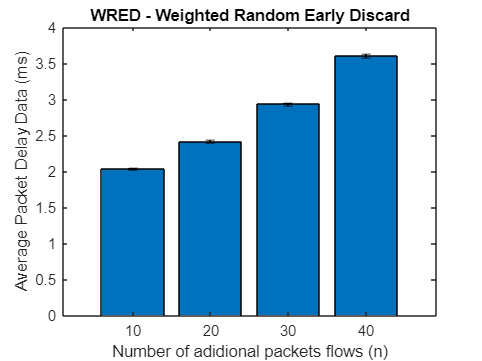



% Plot the results
figure(1)
bar(categorical(n), pkt_delay_data)
title("WRED - Queue with Data Packets")
xlabel("Number of adidional packets flows (n)")
ylabel("Average Packet Delay Data (ms)")
hold on
er = errorbar(categorical(n), pkt_delay_data, error_delay_data, error_delay_data);
er.Color = [0 0 0];
er.LineStyle = 'none';
hold off;

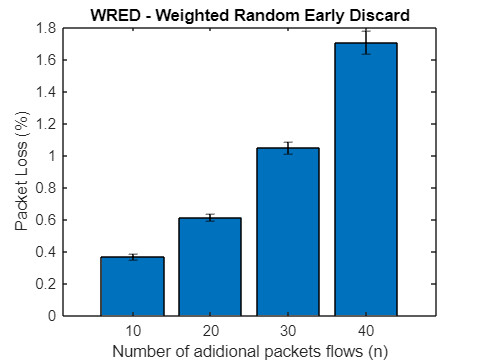


%%% Plot the results
figure(2)
bar(categorical(n), pkt_loss_data)
title("WRED - Queue with Data Packets")
xlabel("Number of adidional packets flows (n)")
ylabel("Packet Loss (%)")
hold on
%%% Adding arror bars to the Plot
er = errorbar(categorical(n), pkt_loss_data, error_loss_data, error_loss_data);
er.Color = [0 0 0];
er.LineStyle = 'none';
hold off;

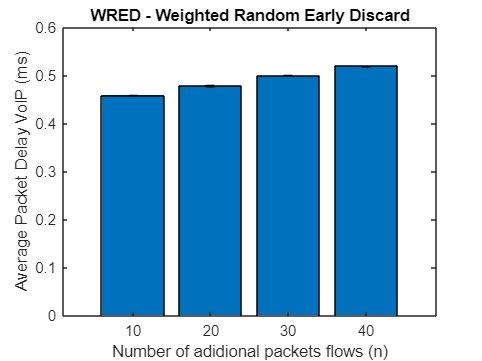


% Plot the results
figure(3)
bar(categorical(n), pkt_delay_voip)
title("WRED - Queue with Data Packets")
xlabel("Number of adidional packets flows (n)")
ylabel("Average Packet Delay VoIP (ms)")
hold on
er = errorbar(categorical(n), pkt_delay_voip, error_delay_voip, error_delay_voip);
er.Color = [0 0 0];
er.LineStyle = 'none';
hold off;

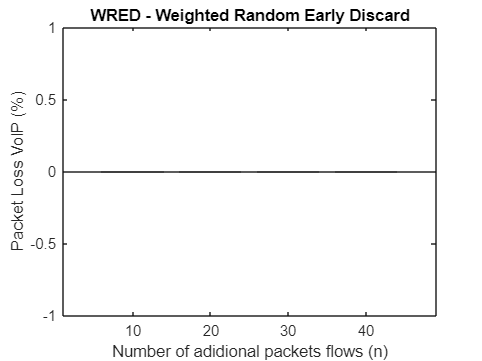


%%% Plot the results
figure(4)
bar(categorical(n), pkt_loss_voip)
title("WRED - Queue with Data Packets")
xlabel("Number of adidional packets flows (n)")
ylabel("Packet Loss VoIP (%)")
hold on
%%% Adding arror bars to the Plot
er = errorbar(categorical(n), pkt_loss_voip, error_loss_voip, error_loss_voip);
er.Color = [0 0 0];
er.LineStyle = 'none';
hold off;

%{ 
conclusão:  
Analisando os resultados obtidos concluímos que a taxa de atrasos e perdas de pacotes
aumenta à medida que aumentam o número de fluxos de pacotes VoIP. No entanto tendo em
conta que os pacotes de dados não são aceites se a taxa de ocupação da fila de espera for
maior que 90%, observamos então que os atrasos de pacotes VoIP aumentam muito pouco,
enquanto que a perda de pacotes do mesmo tipo é nula. Isto ocorre não só pela condição
referida anteriormente mas também pelo facto dos pacotes VoIP terem prioridade sobre os de
dados.
%}
